%% =========================================================
%  PROCESAMIENTO DE SEÑAL EMG - Procesamiento de Señales II
%  Universidad del Magdalena
%  Músculo: Bíceps Braquial y Antebrazo (Flexores)
%  Módulo: AD8232 | ESP32 | fs = 1000 Hz
%  Protocolo: Reposo y flexión voluntaria del codo
%  Electrodos: (+) parte superior bíceps, (−) vientre bíceps
%              (R) antebrazo zona neutra
%  Autor: [Tu nombre]
%  Fecha: 2026
%  NOTA: El AD8232 es para ECG (0.5-40Hz), no para EMG (20-500Hz).
%        Las señales capturadas tienen atenuación >40Hz.
%        Los umbrales y criterios están ajustados por esta limitación.
%  Activación/Reposo: Método Otsu automático
%  Fatiga muscular: Doble detección independiente de Otsu
%    - Frecuencia mediana (disminución >10%)
%    - RMS (aumento >20% en etapa final)
%    - SOLO genera gráfica si se detecta fatiga real
%  Carpetas de salida:
%    - Señales_Procesadas/ → archivos .mat individuales
%    - Bases_Datos/        → archivos Excel
%    - Raíz                → emg_registro_activo.mat
% ==========================================================

%% =========================================================
%  AVISO IMPORTANTE AL USUARIO
% ==========================================================

fprintf('=========================================================\n');

fprintf('  PROCESAMIENTO DE SEÑAL EMG - Bíceps Braquial\n');

  PROCESAMIENTO DE SEÑAL EMG - Bíceps Braquial


fprintf('  NOTA: AD8232 = ECG (0.5-40Hz), EMG esperado (20-500Hz)\n');

  NOTA: AD8232 = ECG (0.5-40Hz), EMG esperado (20-500Hz)


fprintf('  Activación/Reposo: Método Otsu automático\n');

  Activación/Reposo: Método Otsu automático


fprintf('  Fatiga muscular:   Frecuencia mediana + RMS\n');

  Fatiga muscular:   Frecuencia mediana + RMS


fprintf('  Las métricas pueden estar sesgadas por el hardware.\n');

  Las métricas pueden estar sesgadas por el hardware.


fprintf('=========================================================\n\n');


%% =========================================================
%  SECCIÓN 1: CARGA DE DATOS (3 MODOS DE SELECCIÓN)
% ==========================================================

clear; clc; close all;

fprintf('=== SELECCIÓN DE MODO DE CARGA ===\n');

=== SELECCIÓN DE MODO DE CARGA ===


fprintf('1. Procesar una nueva señal (archivo crudo)\n');

1. Procesar una nueva señal (archivo crudo)


fprintf('2. Procesar y comparar DOS señales nuevas\n');

2. Procesar y comparar DOS señales nuevas


fprintf('3. Comparar señales YA PROCESADAS (sin recalcular)\n');

3. Comparar señales YA PROCESADAS (sin recalcular)


opcion_carga = input('Seleccione una opción (1/2/3): ');

hay_comparacion_directa = false;
nombre_ant = '';
nombre_act = '';

switch opcion_carga
    case 1
        fprintf('\n--- MODO SELECCIÓN MANUAL (UNA SEÑAL) ---\n');
        fprintf('Seleccione el archivo .mat de la señal a procesar:\n');
        [nombre_archivo, ruta_archivo] = uigetfile('*.mat', 'Seleccionar archivo de señal EMG');
        if nombre_archivo == 0
            error('No se seleccionó ningún archivo. Programa cancelado.');
        end
        ruta_completa = fullfile(ruta_archivo, nombre_archivo);
        fprintf('Archivo seleccionado: %s\n', nombre_archivo);
        [tiempo, amplitud, fs] = cargar_senal_generica(ruta_completa);
        fprintf('✓ Archivo cargado exitosamente.\n\n');
        
    case 2
        fprintf('\n--- MODO COMPARACIÓN DIRECTA (DOS SEÑALES NUEVAS) ---\n');
        fprintf('Paso 1/2: Seleccione la señal ANTERIOR (más antigua):\n');
        [nombre_ant, ruta_ant] = uigetfile('*.mat', 'Seleccionar señal ANTERIOR (más antigua)');
        if nombre_ant == 0
            error('No se seleccionó la señal anterior. Programa cancelado.');
        end
        fprintf('Archivo ANTERIOR: %s\n', nombre_ant);
        fprintf('\nPaso 2/2: Seleccione la señal ACTUAL (más reciente):\n');
        [nombre_act, ruta_act] = uigetfile('*.mat', 'Seleccionar señal ACTUAL (más reciente)');
        if nombre_act == 0
            error('No se seleccionó la señal actual. Programa cancelado.');
        end
        fprintf('Archivo ACTUAL: %s\n\n', nombre_act);
        [tiempo_ant, amplitud_ant, fs_ant] = cargar_senal_generica(fullfile(ruta_ant, nombre_ant));
        [tiempo_act, amplitud_act, fs_act] = cargar_senal_generica(fullfile(ruta_act, nombre_act));
        tiempo = tiempo_act; amplitud = amplitud_act; fs = fs_act;
        hay_comparacion_directa = true;
        fprintf('✓ Ambas señales cargadas exitosamente.\n');
        fprintf('  Anterior: %d muestras, %.2f s\n', length(amplitud_ant), max(tiempo_ant));
        fprintf('  Actual:   %d muestras, %.2f s\n\n', length(amplitud_act), max(tiempo_act));
        
    case 3
        fprintf('\n--- MODO COMPARACIÓN DE SEÑALES YA PROCESADAS ---\n');
        fprintf('Paso 1/2: Seleccione la señal ANTERIOR (ya procesada):\n');
        [nombre_ant, ruta_ant] = uigetfile('*.mat', 'Seleccionar señal ANTERIOR procesada');
        if nombre_ant == 0
            error('No se seleccionó la señal anterior. Programa cancelado.');
        end
        fprintf('Archivo ANTERIOR: %s\n', nombre_ant);
        datos_ant = load(fullfile(ruta_ant, nombre_ant));
        if isfield(datos_ant, 'registro_anterior')
            reg_ant = datos_ant.registro_anterior;
        elseif isfield(datos_ant, 'registro_nuevo')
            reg_ant = datos_ant.registro_nuevo;
        elseif isfield(datos_ant, 'emg_filtrada') && isfield(datos_ant, 'emg_envolvente')
            reg_ant = datos_ant;
        else
            fprintf('Variables encontradas: '); disp(fieldnames(datos_ant));
            error('El archivo no parece ser una señal procesada. Use la opción 2.');
        end
        fprintf('\nPaso 2/2: Seleccione la señal ACTUAL (ya procesada):\n');
        [nombre_act, ruta_act] = uigetfile('*.mat', 'Seleccionar señal ACTUAL procesada');
        if nombre_act == 0
            error('No se seleccionó la señal actual. Programa cancelado.');
        end
        fprintf('Archivo ACTUAL: %s\n\n', nombre_act);
        datos_act = load(fullfile(ruta_act, nombre_act));
        if isfield(datos_act, 'registro_anterior')
            reg_act = datos_act.registro_anterior;
        elseif isfield(datos_act, 'registro_nuevo')
            reg_act = datos_act.registro_nuevo;
        elseif isfield(datos_act, 'emg_filtrada') && isfield(datos_act, 'emg_envolvente')
            reg_act = datos_act;
        else
            error('El segundo archivo no parece ser una señal procesada.');
        end
        fprintf('✓ Ambas señales procesadas cargadas exitosamente.\n\n');
        
        fprintf('=========================================================\n');
        fprintf('  COMPARACIÓN DE SEÑALES YA PROCESADAS\n');
        fprintf('=========================================================\n\n');
        fprintf('%-35s %-22s %-22s\n', 'Parámetro', 'ANTERIOR', 'ACTUAL');
        fprintf('%s\n', repmat('-', 1, 80));
        fprintf('%-35s %-22s %-22s\n', 'Fecha', reg_ant.fecha, reg_act.fecha);
        fprintf('%-35s %-22.6f %-22.6f\n', 'RMS global (V)', reg_ant.RMS_global, reg_act.RMS_global);
        fprintf('%-35s %-22.6f %-22.6f\n', 'MAV global (V)', reg_ant.MAV_global, reg_act.MAV_global);
        fprintf('%-35s %-22.6f %-22.6f\n', 'Energía (V²)', reg_ant.energia, reg_act.energia);
        fprintf('%-35s %-22.4f %-22.4f\n', 'Amplitud p-p (V)', reg_ant.amplitud_ptp, reg_act.amplitud_ptp);
        fprintf('%-35s %-22.2f %-22.2f\n', 'Frec. mediana (Hz)', reg_ant.frec_mediana, reg_act.frec_mediana);
        fprintf('%-35s %-22.6f %-22.6f\n', 'RMS reposo (V)', reg_ant.RMS_reposo, reg_act.RMS_reposo);
        fprintf('%-35s %-22.6f %-22.6f\n', 'RMS contracción (V)', reg_ant.RMS_contraccion, reg_act.RMS_contraccion);
        fprintf('%-35s %-22.2f %-22.2f\n', 'Relación act/rep', reg_ant.relacion_activacion, reg_act.relacion_activacion);
        fprintf('%-35s %-22.1f %-22.1f\n', '%% Reposo', reg_ant.porcentaje_reposo, reg_act.porcentaje_reposo);
        fprintf('%-35s %-22.1f %-22.1f\n', '%% Activación', reg_ant.porcentaje_activo, reg_act.porcentaje_activo);
        fprintf('%-35s %-22s %-22s\n', '¿Condición normal?', ...
            string_condicion(reg_ant.condicion_normal), string_condicion(reg_act.condicion_normal));
        fprintf('\n');
        
        figure('Name', 'Comparación - Envolvente EMG', 'NumberTitle', 'off');
        subplot(2,1,1); plot(reg_ant.tiempo, reg_ant.emg_envolvente, 'b', 'LineWidth', 1.2);
        xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title(['Envolvente ANTERIOR — ', reg_ant.fecha]); grid on;
        subplot(2,1,2); plot(reg_act.tiempo, reg_act.emg_envolvente, 'r', 'LineWidth', 1.2);
        xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title(['Envolvente ACTUAL — ', reg_act.fecha]); grid on;
        
        figure('Name', 'Comparación - RMS por Ventanas', 'NumberTitle', 'off'); hold on;
        plot(reg_ant.t_ventanas, reg_ant.RMS_ventanas, 'bo-', 'LineWidth', 1.2, 'MarkerFaceColor', 'b');
        plot(reg_act.t_ventanas, reg_act.RMS_ventanas, 'rs-', 'LineWidth', 1.2, 'MarkerFaceColor', 'r');
        xlabel('Tiempo (s)'); ylabel('RMS (V)'); title('Comparación RMS por Ventanas');
        legend('Señal ANTERIOR', 'Señal ACTUAL'); grid on;
        
        N_ant = length(reg_ant.emg_filtrada); N_act = length(reg_act.emg_filtrada);
        f_ant = (0:N_ant-1) * (reg_ant.fs / N_ant); f_act = (0:N_act-1) * (reg_act.fs / N_act);
        idx_a = f_ant >= 20 & f_ant <= reg_ant.fs/2; idx_b = f_act >= 20 & f_act <= reg_act.fs/2;
        FFT_ant = abs(fft(reg_ant.emg_filtrada)) / N_ant; FFT_act = abs(fft(reg_act.emg_filtrada)) / N_act;
        figure('Name', 'Comparación - FFT EMG', 'NumberTitle', 'off');
        plot(f_ant(idx_a), FFT_ant(idx_a), 'b', 'LineWidth', 1); hold on;
        plot(f_act(idx_b), FFT_act(idx_b), 'r', 'LineWidth', 1);
        xlabel('Frecuencia (Hz)'); ylabel('|X(f)|'); title('Comparación Espectral FFT — EMG');
        legend('Señal ANTERIOR', 'Señal ACTUAL'); grid on;
        fprintf('Comparación de señales procesadas completada.\n');
        fprintf('(No se recalcularon filtros ni umbrales)\n\n');
        return;
        
    otherwise
        error('Opción no válida. Debe ser 1, 2 o 3.');
end


--- MODO SELECCIÓN MANUAL (UNA SEÑAL) ---


Seleccione el archivo .mat de la señal a procesar:


Archivo seleccionado: emg_20260508_145304.mat


✓ Archivo cargado exitosamente.




if fs ~= 1000
    fprintf('NOTA: fs detectada = %d Hz\n', fs);
    fprintf('Se recomienda fs = 1000 Hz para EMG.\n\n');
else
    fprintf('fs = 1000 Hz correcta para EMG.\n\n');
end

fs = 1000 Hz correcta para EMG.




fprintf('=== SEÑAL EMG CARGADA ===\n');

=== SEÑAL EMG CARGADA ===


fprintf('Frecuencia de muestreo : %d Hz\n', fs);

Frecuencia de muestreo : 1000 Hz


fprintf('Total de muestras      : %d\n', length(amplitud));

Total de muestras      : 64512


fprintf('Duración               : %.2f segundos\n', max(tiempo));

Duración               : 64.72 segundos


fprintf('Amplitud mínima        : %.4f V\n', min(amplitud));

Amplitud mínima        : 1.3079 V


fprintf('Amplitud máxima        : %.4f V\n\n', max(amplitud));

Amplitud máxima        : 1.7382 V



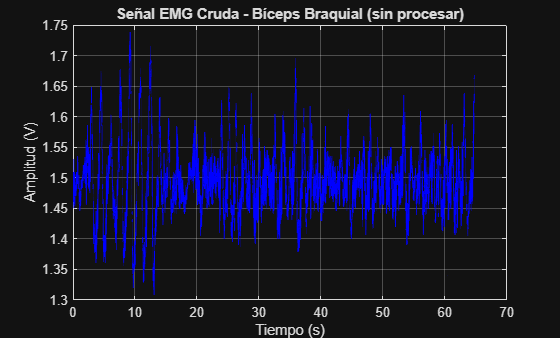


emg_cruda = amplitud;

%% =========================================================
%  SECCIÓN 2: VISUALIZACIÓN DE SEÑAL CRUDA
% ==========================================================

figure('Name', 'Señal EMG Cruda - Bíceps Braquial', 'NumberTitle', 'off');
plot(tiempo, emg_cruda, 'b', 'LineWidth', 0.8);
xlabel('Tiempo (s)'); ylabel('Amplitud (V)');
title('Señal EMG Cruda - Bíceps Braquial (sin procesar)'); grid on;


%% =========================================================
%  SECCIÓN 3: FILTRO PASA ALTO
% ==========================================================

fc_alto = 20; orden_pa = 4; Wn_pa = fc_alto / (fs/2);
[b_pa, a_pa] = butter(orden_pa, Wn_pa, 'high');
emg_sin_deriva = filtfilt(b_pa, a_pa, emg_cruda);
fprintf('=== FILTRO PASA ALTO ===\n');

=== FILTRO PASA ALTO ===


fprintf('Tipo: Butterworth orden %d, Fc = %d Hz\n\n', orden_pa, fc_alto);

Tipo: Butterworth orden 4, Fc = 20 Hz




%% =========================================================
%  SECCIÓN 4: FILTRO NOTCH 60 Hz
% ==========================================================

f_notch = 60; ancho_bw = 2;
Wn_notch = [f_notch - ancho_bw/2, f_notch + ancho_bw/2] / (fs/2);
[b_notch, a_notch] = butter(2, Wn_notch, 'stop');
emg_sin_notch = filtfilt(b_notch, a_notch, emg_sin_deriva);
fprintf('=== FILTRO NOTCH ===\n');

=== FILTRO NOTCH ===


fprintf('Frecuencia eliminada: %d Hz\n\n', f_notch);

Frecuencia eliminada: 60 Hz




%% =========================================================
%  SECCIÓN 5: FILTRO PASA BANDA
% ==========================================================

fc_low = 20; fc_high = 490; orden_pb = 4;
Wn_pb = [fc_low, fc_high] / (fs/2);
[b_pb, a_pb] = butter(orden_pb, Wn_pb, 'bandpass');
emg_filtrada = filtfilt(b_pb, a_pb, emg_sin_notch);
fprintf('=== FILTRO PASA BANDA ===\n');

=== FILTRO PASA BANDA ===


fprintf('Tipo: Butterworth orden %d, Fc = [%d, %d] Hz\n', orden_pb, fc_low, fc_high);

Tipo: Butterworth orden 4, Fc = [20, 490] Hz


fprintf('NOTA: AD8232 atenúa >40Hz, filtro digital no recupera eso.\n\n');

NOTA: AD8232 atenúa >40Hz, filtro digital no recupera eso.



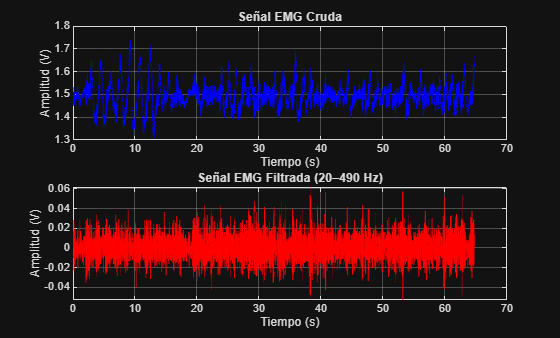


%% =========================================================
%  SECCIÓN 6: VISUALIZACIÓN SEÑAL CRUDA VS FILTRADA
% ==========================================================

figure('Name', 'Comparación: Cruda vs Filtrada', 'NumberTitle', 'off');
subplot(2,1,1); plot(tiempo, emg_cruda, 'b', 'LineWidth', 0.8);
xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title('Señal EMG Cruda'); grid on;
subplot(2,1,2); plot(tiempo, emg_filtrada, 'r', 'LineWidth', 0.8);
xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title('Señal EMG Filtrada (20–490 Hz)'); grid on;

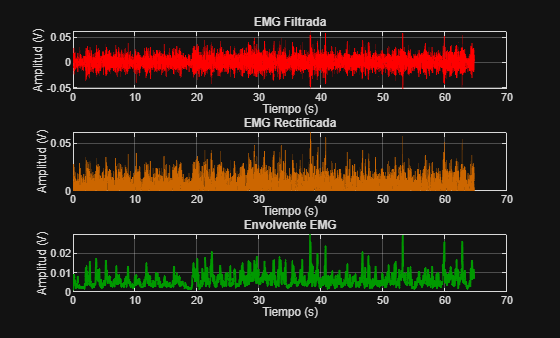


%% =========================================================
%  SECCIÓN 7: RECTIFICACIÓN Y ENVOLVENTE
% ==========================================================

emg_rectificada = abs(emg_filtrada);
fc_env = 10; Wn_env = fc_env / (fs/2);
[b_env, a_env] = butter(4, Wn_env, 'low');
emg_envolvente = filtfilt(b_env, a_env, emg_rectificada);

figure('Name', 'Rectificación y Envolvente EMG', 'NumberTitle', 'off');
subplot(3,1,1); plot(tiempo, emg_filtrada, 'r', 'LineWidth', 0.8);
xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title('EMG Filtrada'); grid on;
subplot(3,1,2); plot(tiempo, emg_rectificada, 'Color', [0.8 0.4 0], 'LineWidth', 0.8);
xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title('EMG Rectificada'); grid on;
subplot(3,1,3); plot(tiempo, emg_envolvente, 'Color', [0 0.6 0], 'LineWidth', 1.5);
xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title('Envolvente EMG'); grid on;

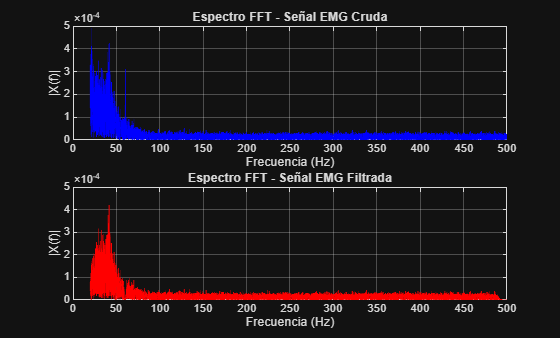


%% =========================================================
%  SECCIÓN 8: ANÁLISIS EN FRECUENCIA - FFT
% ==========================================================

N = length(emg_filtrada); f_eje = (0:N-1) * (fs/N); idx = f_eje >= 20 & f_eje <= fs/2;
FFT_cruda = abs(fft(emg_cruda)) / N; FFT_filtrada = abs(fft(emg_filtrada)) / N;

figure('Name', 'Espectro de Frecuencia - FFT', 'NumberTitle', 'off');
subplot(2,1,1); plot(f_eje(idx), FFT_cruda(idx), 'b', 'LineWidth', 0.8);
xlabel('Frecuencia (Hz)'); ylabel('|X(f)|'); title('Espectro FFT - Señal EMG Cruda'); grid on;
subplot(2,1,2); plot(f_eje(idx), FFT_filtrada(idx), 'r', 'LineWidth', 0.8);
xlabel('Frecuencia (Hz)'); ylabel('|X(f)|'); title('Espectro FFT - Señal EMG Filtrada'); grid on;


%% =========================================================
%  SECCIÓN 9: ESPECTROGRAMA
% ==========================================================

ventana_esp = round(fs * 0.256); overlap_esp = round(ventana_esp * 0.75); nfft_esp = 1024;
figure('Name', 'Espectrograma EMG', 'NumberTitle', 'off');
spectrogram(emg_filtrada, hamming(ventana_esp), overlap_esp, nfft_esp, fs, 'yaxis');
title('Espectrograma - Señal EMG Bíceps Braquial'); ylim([0 500]); colorbar;


%% =========================================================
%  SECCIÓN 10: EXTRACCIÓN DE CARACTERÍSTICAS POR VENTANAS
% ==========================================================

tam_ventana = round(0.250 * fs); n_ventanas = floor(length(emg_filtrada) / tam_ventana);
RMS_ventanas = zeros(1, n_ventanas); MAV_ventanas = zeros(1, n_ventanas);
ENE_ventanas = zeros(1, n_ventanas); t_ventanas = zeros(1, n_ventanas);

for i = 1:n_ventanas
    ini = (i-1)*tam_ventana + 1; fin = i * tam_ventana;
    segmento = emg_filtrada(ini:fin);
    RMS_ventanas(i) = rms(segmento); MAV_ventanas(i) = mean(abs(segmento));
    ENE_ventanas(i) = sum(segmento.^2) / tam_ventana; t_ventanas(i) = tiempo(ini);
end

figure('Name', 'Características por Ventanas', 'NumberTitle', 'off');
subplot(3,1,1); stem(t_ventanas, RMS_ventanas, 'filled', 'Color', 'r');
xlabel('Tiempo (s)'); ylabel('RMS (V)'); title('RMS por ventanas (250 ms)'); grid on;
subplot(3,1,2); stem(t_ventanas, MAV_ventanas, 'filled', 'Color', [0 0.5 0]);
xlabel('Tiempo (s)'); ylabel('MAV (V)'); title('MAV por ventanas'); grid on;
subplot(3,1,3); stem(t_ventanas, ENE_ventanas, 'filled', 'Color', [0.5 0 0.5]);
xlabel('Tiempo (s)'); ylabel('Energía (V²)'); title('Energía por ventanas'); grid on;


%% =========================================================
%  SECCIÓN 11: FRECUENCIA MEDIANA GLOBAL
% ==========================================================

potencia_esp = FFT_filtrada(idx).^2; f_validas = f_eje(idx);
frec_mediana = f_validas(find(cumsum(potencia_esp) >= sum(potencia_esp)/2, 1));

fprintf('=== CARACTERÍSTICAS GLOBALES ===\n');

=== CARACTERÍSTICAS GLOBALES ===


fprintf('RMS global      : %.6f V\n', rms(emg_filtrada));

RMS global      : 0.008624 V


fprintf('MAV global      : %.6f V\n', mean(abs(emg_filtrada)));

MAV global      : 0.006245 V


fprintf('Energía norm.   : %.6f V²\n', sum(emg_filtrada.^2)/length(emg_filtrada));

Energía norm.   : 0.000074 V²


fprintf('Amplitud p-p    : %.4f V\n', peak2peak(emg_filtrada));

Amplitud p-p    : 0.1147 V


fprintf('Frec. mediana   : %.2f Hz', frec_mediana);

Frec. mediana   : 39.09 Hz

if frec_mediana < 60, fprintf(' (baja - esperable por AD8232)'); end

 (baja - esperable por AD8232)

fprintf('\n\n');

%% =========================================================
%  SECCIÓN 12: IDENTIFICACIÓN DE CONDICIONES NORMALES (OTSU)
% ==========================================================

fprintf('=== IDENTIFICACIÓN DE CONDICIONES NORMALES ===\n');

=== IDENTIFICACIÓN DE CONDICIONES NORMALES ===


fprintf('(Evaluación académica - NO es diagnóstico clínico)\n');

(Evaluación académica - NO es diagnóstico clínico)


fprintf('Método de umbral: Otsu automático\n\n');

Método de umbral: Otsu automático




RMS_ordenado = sort(RMS_ventanas); n_ventanas_total = length(RMS_ventanas);

if max(RMS_ventanas) > min(RMS_ventanas)
    umbrales_prueba = linspace(min(RMS_ventanas), max(RMS_ventanas), 100);
    mejor_varianza = -inf; mejor_umbral_otsu = min(RMS_ventanas);
    for u = umbrales_prueba
        grupo_bajo = RMS_ordenado(RMS_ordenado <= u); grupo_alto = RMS_ordenado(RMS_ordenado > u);
        if ~isempty(grupo_bajo) && ~isempty(grupo_alto)
            varianza_entre = length(grupo_bajo) * length(grupo_alto) * (mean(grupo_alto) - mean(grupo_bajo))^2;
            if varianza_entre > mejor_varianza
                mejor_varianza = varianza_entre; mejor_umbral_otsu = u;
            end
        end
    end
    umbral_activacion = mejor_umbral_otsu;
else
    umbral_activacion = mean(RMS_ventanas);
end

fprintf('✓ Umbral automático (Otsu): %.6f V\n\n', umbral_activacion);

✓ Umbral automático (Otsu): 0.008653 V




ventanas_activas = RMS_ventanas > umbral_activacion; ventanas_reposo = ~ventanas_activas;
porcentaje_activo = (sum(ventanas_activas) / n_ventanas_total) * 100;
porcentaje_reposo = (sum(ventanas_reposo) / n_ventanas_total) * 100;

RMS_reposo = 0; RMS_contraccion = 0;
if sum(ventanas_reposo) > 0, RMS_reposo = mean(RMS_ventanas(ventanas_reposo)); end
if sum(ventanas_activas) > 0, RMS_contraccion = mean(RMS_ventanas(ventanas_activas)); end

fprintf('=== RESULTADOS DE CLASIFICACIÓN ===\n');

=== RESULTADOS DE CLASIFICACIÓN ===


fprintf('Umbral de activación    : %.6f V\n', umbral_activacion);

Umbral de activación    : 0.008653 V


fprintf('Ventanas en reposo      : %d (%.1f%%)\n', sum(ventanas_reposo), porcentaje_reposo);

Ventanas en reposo      : 160 (62.0%)


fprintf('Ventanas en activación  : %d (%.1f%%)\n', sum(ventanas_activas), porcentaje_activo);

Ventanas en activación  : 98 (38.0%)


fprintf('RMS promedio reposo     : %.6f V\n', RMS_reposo);

RMS promedio reposo     : 0.006031 V


fprintf('RMS promedio contracción: %.6f V\n\n', RMS_contraccion);

RMS promedio contracción: 0.011254 V




if RMS_reposo > 0
    relacion_activacion = RMS_contraccion / RMS_reposo;
    fprintf('Relación activación/reposo: %.2f x\n\n', relacion_activacion);
else
    relacion_activacion = NaN;
end

Relación activación/reposo: 1.87 x




figure('Name', 'Identificación Reposo vs Activación (Otsu)', 'NumberTitle', 'off');
subplot(2,1,1); plot(tiempo, emg_envolvente, 'Color', [0 0.6 0], 'LineWidth', 1.5); hold on;
yline(umbral_activacion, 'r--', 'LineWidth', 2, 'Label', sprintf('Umbral Otsu = %.4f V', umbral_activacion));
for i = 1:n_ventanas_total
    if ventanas_activas(i)
        t_ini = t_ventanas(i); t_fin = t_ini + 0.250;
        x_patch = [t_ini t_fin t_fin t_ini]; y_patch = [0 0 max(emg_envolvente) max(emg_envolvente)];
        patch(x_patch, y_patch, 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
    end
end
xlabel('Tiempo (s)'); ylabel('Amplitud (V)');
title('Envolvente EMG - Zonas de Activación (rojo) y Reposo');
legend('Envolvente', 'Umbral Otsu', 'Activación'); grid on;
subplot(2,1,2); stem(t_ventanas, RMS_ventanas, 'filled', 'Color', [0.4 0.4 1], 'LineWidth', 1.5); hold on;
yline(umbral_activacion, 'r--', 'LineWidth', 2, 'Label', 'Umbral Otsu');
stem(t_ventanas(ventanas_activas), RMS_ventanas(ventanas_activas), 'filled', 'Color', 'r', 'LineWidth', 1.5);
xlabel('Tiempo (s)'); ylabel('RMS (V)'); title('RMS por Ventanas - Puntos rojos = Activación');
legend('Reposo', 'Umbral', 'Activación'); grid on;


condicion_normal = true; observaciones = {};
fprintf('=== EVALUACIÓN DE CONDICIONES ===\n');

=== EVALUACIÓN DE CONDICIONES ===


fprintf('(Criterios ajustados por limitación del AD8232)\n');

(Criterios ajustados por limitación del AD8232)


if porcentaje_activo >= 3
    fprintf('[OK] Activación detectada: %.1f%%\n', porcentaje_activo);
else
    fprintf('[ATENCIÓN] Poca activación: %.1f%% (< 3%%)\n', porcentaje_activo);
    condicion_normal = false; observaciones{end+1} = 'Pocas ventanas activas';
end

[OK] Activación detectada: 38.0%


if porcentaje_reposo >= 10
    fprintf('[OK] Reposo identificado: %.1f%%\n', porcentaje_reposo);
else
    fprintf('[ATENCIÓN] Poco reposo: %.1f%%\n', porcentaje_reposo);
    condicion_normal = false; observaciones{end+1} = 'Señal con actividad casi continua';
end

[OK] Reposo identificado: 62.0%


if ~isnan(relacion_activacion) && relacion_activacion >= 1.5
    fprintf('[OK] Relación act/rep: %.2f x (>= 1.5x)\n', relacion_activacion);
elseif ~isnan(relacion_activacion)
    fprintf('[ATENCIÓN] Relación baja: %.2f x\n', relacion_activacion);
    observaciones{end+1} = 'Relación act/rep baja';
end

[OK] Relación act/rep: 1.87 x (>= 1.5x)


if frec_mediana >= 30 && frec_mediana <= 150
    fprintf('[OK] Frec. mediana: %.2f Hz\n', frec_mediana);
else
    fprintf('[ATENCIÓN] Frec. mediana: %.2f Hz\n', frec_mediana);
    observaciones{end+1} = 'Frecuencia mediana atípica';
end

[OK] Frec. mediana: 39.09 Hz


fprintf('\n--- RESULTADO FINAL ---\n');


--- RESULTADO FINAL ---


if condicion_normal
    fprintf('REGISTRO COMPATIBLE con actividad muscular fisiológica.\n');
    fprintf('Reposo: %.1f%% | Activación: %.1f%%\n', porcentaje_reposo, porcentaje_activo);
else
    fprintf('REGISTRO CON OBSERVACIONES:\n');
    for i = 1:length(observaciones), fprintf('  • %s\n', observaciones{i}); end
end

REGISTRO COMPATIBLE con actividad muscular fisiológica.


Reposo: 62.0% | Activación: 38.0%


fprintf('(Resultado académico, no clínico)\n');

(Resultado académico, no clínico)


fprintf('(Limitación: AD8232 atenúa >40Hz)\n\n');

(Limitación: AD8232 atenúa >40Hz)




%% =========================================================
%  SECCIÓN 12B: ANÁLISIS DE FATIGA MUSCULAR
%  DOBLE DETECCIÓN (INDEPENDIENTE DE OTSU)
%  SOLO genera gráfica si se detecta fatiga real
% ==========================================================

fprintf('=== ANÁLISIS DE FATIGA MUSCULAR ===\n');

=== ANÁLISIS DE FATIGA MUSCULAR ===


fprintf('(Evaluación académica - NO es diagnóstico clínico)\n');

(Evaluación académica - NO es diagnóstico clínico)


fprintf('Método: Doble detección independiente de Otsu\n');

Método: Doble detección independiente de Otsu


fprintf('  1. Frecuencia mediana (disminución >10%%)\n');

  1. Frecuencia mediana (disminución >10%)


fprintf('  2. Amplitud RMS (aumento >20%% en etapa final)\n\n');

  2. Amplitud RMS (aumento >20% en etapa final)




tam_vent_fat = round(0.500 * fs); paso_fat = round(0.250 * fs);
N_total = length(emg_filtrada);
n_vent_fat = floor((N_total - tam_vent_fat) / paso_fat) + 1;

fmed_vent = zeros(1, n_vent_fat); rms_vent_fat = zeros(1, n_vent_fat);
t_vent_fat = zeros(1, n_vent_fat);

for i = 1:n_vent_fat
    ini_m = (i-1)*paso_fat + 1; fin_m = ini_m + tam_vent_fat - 1;
    if fin_m <= N_total
        seg = emg_filtrada(ini_m:fin_m);
        t_vent_fat(i) = tiempo(ini_m + round(tam_vent_fat/2));
        rms_vent_fat(i) = rms(seg);
        N_seg = length(seg); fft_seg = abs(fft(seg)) / N_seg;
        f_eje_seg = (0:N_seg-1) * (fs/N_seg); idx_f_seg = f_eje_seg >= 20 & f_eje_seg <= fs/2;
        pot_seg = fft_seg(idx_f_seg).^2; f_val_seg = f_eje_seg(idx_f_seg);
        if sum(pot_seg) > 0
            fmed_vent(i) = f_val_seg(find(cumsum(pot_seg) >= sum(pot_seg)/2, 1));
        else
            fmed_vent(i) = NaN;
        end
    end
end

idx_val = ~isnan(fmed_vent);
hay_fatiga = false;

--- ANÁLISIS POR TERCIOS (Inicio vs Final) ---


  PRIMER TERCIO:


    RMS promedio : 0.006959 V


    Fmed promedio: 64.3 Hz


  ÚLTIMO TERCIO:


    RMS promedio : 0.008395 V


    Fmed promedio: 42.9 Hz


  CAMBIOS:


    RMS  : +20.6% ↑ (AUMENTA)


    Fmed : -33.3% ↓ (DISMINUYE)



--- DETECCIÓN DE FATIGA ---


  [✓] Frecuencia mediana DISMINUYÓ >10% → INDICIO DE FATIGA


  [✓] Amplitud RMS AUMENTÓ >20% en etapa final → INDICIO DE FATIGA



  ► Se detectaron INDICIOS DE FATIGA MUSCULAR


    (Ambos indicadores coinciden - alta confiabilidad)


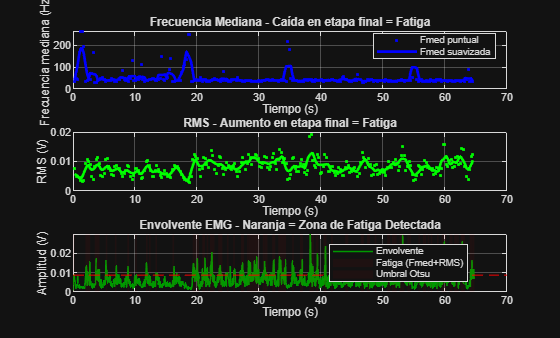


if sum(idx_val) < 5
    fprintf('► Datos insuficientes para análisis de fatiga.\n\n');
else
    vent_suav = 5;
    if length(fmed_vent) >= vent_suav
        fmed_suave = movmean(fmed_vent, vent_suav, 'omitnan');
        rms_suave = movmean(rms_vent_fat, vent_suav);
    else
        fmed_suave = fmed_vent; rms_suave = rms_vent_fat;
    end
    
    n_total_fat = length(rms_suave);
    tercio_fat = round(n_total_fat / 3);
    
    if n_total_fat >= 9
        idx_inicio = 1:tercio_fat;
        rms_inicio_prom = mean(rms_suave(idx_inicio));
        fmed_inicio_prom = mean(fmed_suave(idx_inicio), 'omitnan');
        
        idx_final = (n_total_fat - tercio_fat + 1):n_total_fat;
        rms_final_prom = mean(rms_suave(idx_final));
        fmed_final_prom = mean(fmed_suave(idx_final), 'omitnan');
        
        if rms_inicio_prom > 0
            cambio_rms_pct = ((rms_final_prom - rms_inicio_prom) / rms_inicio_prom) * 100;
        else
            cambio_rms_pct = 0;
        end
        if fmed_inicio_prom > 0
            cambio_fmed_pct = ((fmed_final_prom - fmed_inicio_prom) / fmed_inicio_prom) * 100;
        else
            cambio_fmed_pct = 0;
        end
        
        fprintf('--- ANÁLISIS POR TERCIOS (Inicio vs Final) ---\n');
        fprintf('  PRIMER TERCIO:\n');
        fprintf('    RMS promedio : %.6f V\n', rms_inicio_prom);
        fprintf('    Fmed promedio: %.1f Hz\n', fmed_inicio_prom);
        fprintf('  ÚLTIMO TERCIO:\n');
        fprintf('    RMS promedio : %.6f V\n', rms_final_prom);
        fprintf('    Fmed promedio: %.1f Hz\n', fmed_final_prom);
        fprintf('  CAMBIOS:\n');
        fprintf('    RMS  : %+.1f%% %s\n', cambio_rms_pct, string_flecha(cambio_rms_pct));
        fprintf('    Fmed : %+.1f%% %s\n', cambio_fmed_pct, string_flecha(cambio_fmed_pct));
        
        fatiga_fmed = (cambio_fmed_pct < -10);
        fatiga_rms = (cambio_rms_pct > 20);
        hay_fatiga = fatiga_fmed || fatiga_rms;
        
        fprintf('\n--- DETECCIÓN DE FATIGA ---\n');
        if fatiga_fmed
            fprintf('  [✓] Frecuencia mediana DISMINUYÓ >10%% → INDICIO DE FATIGA\n');
        else
            fprintf('  [ ] Frecuencia mediana sin cambio significativo (> -10%% requerido)\n');
        end
        if fatiga_rms
            fprintf('  [✓] Amplitud RMS AUMENTÓ >20%% en etapa final → INDICIO DE FATIGA\n');
        else
            fprintf('  [ ] Amplitud RMS sin cambio significativo (> +20%% requerido)\n');
        end
        
        if hay_fatiga
            fprintf('\n  ► Se detectaron INDICIOS DE FATIGA MUSCULAR\n');
            if fatiga_fmed && fatiga_rms
                fprintf('    (Ambos indicadores coinciden - alta confiabilidad)\n');
            elseif fatiga_fmed
                fprintf('    (Detectado por frecuencia mediana)\n');
            else
                fprintf('    (Detectado por aumento de amplitud RMS)\n');
            end
            
            % --- SOLO generar gráfica si hay fatiga ---

            figure('Name', 'Análisis de Fatiga Muscular - Doble Detección', 'NumberTitle', 'off');
            
            subplot(3,1,1); plot(t_vent_fat, fmed_vent, 'b.', 'MarkerSize', 6); hold on;
            t_val = t_vent_fat(idx_val);
            plot(t_val, fmed_suave(idx_val), 'b-', 'LineWidth', 2);           
            xlabel('Tiempo (s)'); ylabel('Frecuencia mediana (Hz)');
            title('Frecuencia Mediana - Caída en etapa final = Fatiga');
            legend('Fmed puntual', 'Fmed suavizada', 'Location', 'best'); grid on;
            
            subplot(3,1,2); plot(t_vent_fat, rms_vent_fat, 'g.', 'MarkerSize', 6); hold on;
            plot(t_vent_fat, rms_suave, 'g-', 'LineWidth', 2);
            xlabel('Tiempo (s)'); ylabel('RMS (V)');
            title('RMS - Aumento en etapa final = Fatiga'); grid on;
            
            subplot(3,1,3); plot(tiempo, emg_envolvente, 'Color', [0 0.6 0], 'LineWidth', 1.2); hold on;
            for i = 1:n_ventanas_total
                if ventanas_activas(i)
                    t_ini = t_ventanas(i); t_fin = t_ini + 0.250;
                    x_patch = [t_ini t_fin t_fin t_ini]; y_patch = [0 0 max(emg_envolvente) max(emg_envolvente)];
                    patch(x_patch, y_patch, 'r', 'FaceAlpha', 0.05, 'EdgeColor', 'none');
                end
            end
            yline(umbral_activacion, 'r--', 'LineWidth', 1);
            xlabel('Tiempo (s)'); ylabel('Amplitud (V)');
            title('Envolvente EMG');
            legend('Envolvente', 'Umbral Otsu', 'Location', 'best'); grid on;
        else
            fprintf('\n  ► Sin indicios de fatiga muscular.\n');
            fprintf('    (No se generó gráfica de fatiga)\n');
        end
    else
        fprintf('► Señal demasiado corta para análisis de fatiga.\n\n');
    end
end


fprintf('\n=== RESUMEN DE FATIGA ===\n');


=== RESUMEN DE FATIGA ===


if hay_fatiga
    fprintf('► Se detectaron INDICIOS DE FATIGA MUSCULAR (ver gráfica generada).\n');
else
    fprintf('► No se detectaron indicios de fatiga muscular.\n');
    fprintf('  Posibles razones:\n');
    fprintf('  - Protocolo sin fatiga (ej: solo reposo)\n');
    fprintf('  - Contracciones demasiado cortas\n');
    fprintf('  - Limitación del AD8232\n');
end

► Se detectaron INDICIOS DE FATIGA MUSCULAR (ver gráfica generada).


fprintf('(Análisis académico, no clínico)\n');

(Análisis académico, no clínico)


fprintf('NOTA: Fatiga detectada de forma INDEPENDIENTE a Otsu.\n\n');

NOTA: Fatiga detectada de forma INDEPENDIENTE a Otsu.




%% =========================================================
%  SECCIÓN 13: TABLA RESUMEN
% ==========================================================

fprintf('=== TABLA RESUMEN ===\n');

=== TABLA RESUMEN ===


fprintf('%-35s %-15s\n', 'Parámetro', 'Valor');

Parámetro                           Valor          


fprintf('%s\n', repmat('-', 1, 50));

--------------------------------------------------


fprintf('%-35s %-15.6f\n', 'RMS global (V)', rms(emg_filtrada));

RMS global (V)                      0.008624       


fprintf('%-35s %-15.6f\n', 'MAV global (V)', mean(abs(emg_filtrada)));

MAV global (V)                      0.006245       


fprintf('%-35s %-15.6f\n', 'Energía normalizada (V²)', sum(emg_filtrada.^2)/length(emg_filtrada));

Energía normalizada (V²)            0.000074       


fprintf('%-35s %-15.4f\n', 'Amplitud pico a pico (V)', peak2peak(emg_filtrada));

Amplitud pico a pico (V)            0.1147         


fprintf('%-35s %-15.2f\n', 'Frecuencia mediana (Hz)', frec_mediana);

Frecuencia mediana (Hz)             39.09          


fprintf('%-35s %-15.6f\n', 'RMS reposo (V)', RMS_reposo);

RMS reposo (V)                      0.006031       


fprintf('%-35s %-15.6f\n', 'RMS contracción (V)', RMS_contraccion);

RMS contracción (V)                 0.011254       


fprintf('%-35s %-15.2f\n', 'Relación activación/reposo', relacion_activacion);

Relación activación/reposo          1.87           


fprintf('%-35s %-15.1f\n', 'Porcentaje reposo (%%)', porcentaje_reposo);

Porcentaje reposo (%%)              62.0           


fprintf('%-35s %-15.1f\n', 'Porcentaje activación (%%)', porcentaje_activo);

Porcentaje activación (%%)          38.0           


fprintf('\n');


%% =========================================================
%  SECCIÓN 14A: BASE DE DATOS 1 — SEÑALES CRUDAS
% ==========================================================

carpeta_bd = 'Bases_Datos';
if ~exist(carpeta_bd, 'dir'), mkdir(carpeta_bd); end

archivo_bd_crudas = fullfile(carpeta_bd, 'BD_señales_crudas.xlsx');
fecha_actual = datestr(now, 'yyyy-mm-dd HH:MM:SS');

nueva_fila_cruda = {fecha_actual, fs, max(tiempo), length(emg_cruda), ...
    min(emg_cruda), max(emg_cruda), mean(emg_cruda), peak2peak(emg_cruda)};

if isfile(archivo_bd_crudas)
    bd_crudas = readtable(archivo_bd_crudas);
    nueva_tabla = cell2table(nueva_fila_cruda, 'VariableNames', bd_crudas.Properties.VariableNames);
    bd_crudas = [bd_crudas; nueva_tabla];
else
    bd_crudas = cell2table(nueva_fila_cruda, 'VariableNames', ...
        {'Fecha', 'fs_Hz', 'Duracion_s', 'N_muestras', 'Amplitud_min_V', ...
        'Amplitud_max_V', 'Amplitud_media_V', 'Amplitud_ptp_V'});
end
writetable(bd_crudas, archivo_bd_crudas);
fprintf('=== BASE DE DATOS 1: SEÑALES CRUDAS ===\n');

=== BASE DE DATOS 1: SEÑALES CRUDAS ===


fprintf('Registro añadido: %s (%d registros)\n\n', archivo_bd_crudas, height(bd_crudas));

Registro añadido: Bases_Datos\BD_señales_crudas.xlsx (15 registros)




%% =========================================================
%  SECCIÓN 14B: BASE DE DATOS 2 — SEÑALES PROCESADAS
% ==========================================================

carpeta_procesadas = 'Señales_Procesadas';
if ~exist(carpeta_procesadas, 'dir'), mkdir(carpeta_procesadas); end

archivo_activo = 'emg_registro_activo.mat';
archivo_bd_proc = fullfile(carpeta_bd, 'BD_señales_procesadas.xlsx');

registro_nuevo.fecha = fecha_actual; registro_nuevo.fs = fs;
registro_nuevo.duracion_s = max(tiempo);
registro_nuevo.emg_cruda = emg_cruda; registro_nuevo.emg_filtrada = emg_filtrada;
registro_nuevo.emg_envolvente = emg_envolvente; registro_nuevo.tiempo = tiempo;
registro_nuevo.RMS_global = rms(emg_filtrada);
registro_nuevo.MAV_global = mean(abs(emg_filtrada));
registro_nuevo.energia = sum(emg_filtrada.^2)/length(emg_filtrada);
registro_nuevo.amplitud_ptp = peak2peak(emg_filtrada);
registro_nuevo.frec_mediana = frec_mediana;
registro_nuevo.RMS_reposo = RMS_reposo; registro_nuevo.RMS_contraccion = RMS_contraccion;
registro_nuevo.relacion_activacion = relacion_activacion;
registro_nuevo.porcentaje_reposo = porcentaje_reposo;
registro_nuevo.porcentaje_activo = porcentaje_activo;
registro_nuevo.RMS_ventanas = RMS_ventanas; registro_nuevo.MAV_ventanas = MAV_ventanas;
registro_nuevo.ENE_ventanas = ENE_ventanas; registro_nuevo.t_ventanas = t_ventanas;
registro_nuevo.condicion_normal = condicion_normal;
registro_nuevo.observaciones = observaciones;
registro_nuevo.hay_fatiga = hay_fatiga;

fprintf('=== BASE DE DATOS 2: SEÑALES PROCESADAS ===\n');

=== BASE DE DATOS 2: SEÑALES PROCESADAS ===



fila_actual = {registro_nuevo.fecha, registro_nuevo.fs, registro_nuevo.duracion_s, ...
    registro_nuevo.RMS_global, registro_nuevo.MAV_global, registro_nuevo.energia, ...
    registro_nuevo.amplitud_ptp, registro_nuevo.frec_mediana, ...
    registro_nuevo.RMS_reposo, registro_nuevo.RMS_contraccion, ...
    registro_nuevo.relacion_activacion, registro_nuevo.porcentaje_reposo, ...
    registro_nuevo.porcentaje_activo, registro_nuevo.condicion_normal};

if isfile(archivo_bd_proc)
    bd_proc = readtable(archivo_bd_proc);
    nueva_fila = cell2table(fila_actual, 'VariableNames', bd_proc.Properties.VariableNames);
    bd_proc = [bd_proc; nueva_fila];
else
    bd_proc = cell2table(fila_actual, 'VariableNames', ...
        {'Fecha', 'fs_Hz', 'Duracion_s', 'RMS_global_V', 'MAV_global_V', 'Energia_V2', ...
        'Amplitud_ptp_V', 'Frec_mediana_Hz', 'RMS_reposo_V', 'RMS_contraccion_V', ...
        'Relacion_activacion', 'Porcentaje_reposo', 'Porcentaje_activacion', 'Condicion_normal'});
end
writetable(bd_proc, archivo_bd_proc);
fprintf('✓ Señal archivada en Excel: %s (%d registros)\n', archivo_bd_proc, height(bd_proc));

✓ Señal archivada en Excel: Bases_Datos\BD_señales_procesadas.xlsx (15 registros)



nombre_individual = sprintf('procesada_biceps_%s.mat', datestr(now, 'yyyymmdd_HHMMSS'));
ruta_individual = fullfile(carpeta_procesadas, nombre_individual);
save(ruta_individual, 'registro_nuevo');
fprintf('✓ Señal procesada guardada en: %s\n', ruta_individual);

✓ Señal procesada guardada en: Señales_Procesadas\procesada_biceps_20260515_123259.mat



hay_anterior = false;
if isfile(archivo_activo)
    m_activo = load(archivo_activo, 'registro_anterior');
    reg_anterior = m_activo.registro_anterior;
    hay_anterior = true;
    fprintf('  Registro anterior encontrado.\n\n');
else
    fprintf('  Primer registro procesado.\n\n');
end

  Registro anterior encontrado.



registro_anterior = registro_nuevo;
save(archivo_activo, 'registro_anterior');
fprintf('Señal guardada como registro activo.\n\n');

Señal guardada como registro activo.




%% =========================================================
%  SECCIÓN 15: COMPARACIÓN
% ==========================================================

if hay_comparacion_directa
    fprintf('\n=== COMPARACIÓN DIRECTA DE SEÑALES EMG ===\n\n');
    [emg_filtrada_ant, emg_envolvente_ant, RMS_ventanas_ant, t_ventanas_ant, ...
        FFT_filtrada_ant, f_eje_ant, idx_ant, RMS_reposo_ant, RMS_contraccion_ant, ...
        relacion_act_ant] = procesar_senal_completa(amplitud_ant, fs_ant);
    RMS_global_ant = rms(emg_filtrada_ant); MAV_global_ant = mean(abs(emg_filtrada_ant));
    energia_ant = sum(emg_filtrada_ant.^2)/length(emg_filtrada_ant);
    amp_ptp_ant = peak2peak(emg_filtrada_ant);
    pot_ant = FFT_filtrada_ant(idx_ant).^2; f_val_ant = f_eje_ant(idx_ant);
    frec_mediana_ant = f_val_ant(find(cumsum(pot_ant) >= sum(pot_ant)/2, 1));
    RMS_global_act = rms(emg_filtrada); MAV_global_act = mean(abs(emg_filtrada));
    energia_act = sum(emg_filtrada.^2)/length(emg_filtrada); amp_ptp_act = peak2peak(emg_filtrada);
    
    fprintf('%-35s %-22s %-22s\n', 'Parámetro', 'ANTERIOR', 'ACTUAL');
    fprintf('%s\n', repmat('-', 1, 80));
    fprintf('%-35s %-22.6f %-22.6f\n', 'RMS global (V)', RMS_global_ant, RMS_global_act);
    fprintf('%-35s %-22.6f %-22.6f\n', 'MAV global (V)', MAV_global_ant, MAV_global_act);
    fprintf('%-35s %-22.6f %-22.6f\n', 'Energía (V²)', energia_ant, energia_act);
    fprintf('%-35s %-22.4f %-22.4f\n', 'Amplitud p-p (V)', amp_ptp_ant, amp_ptp_act);
    fprintf('%-35s %-22.2f %-22.2f\n', 'Frec. mediana (Hz)', frec_mediana_ant, frec_mediana);
    fprintf('%-35s %-22.6f %-22.6f\n', 'RMS reposo (V)', RMS_reposo_ant, RMS_reposo);
    fprintf('%-35s %-22.6f %-22.6f\n', 'RMS contracción (V)', RMS_contraccion_ant, RMS_contraccion);
    fprintf('%-35s %-22.2f %-22.2f\n', 'Relación act/rep', relacion_act_ant, relacion_activacion);
    
    figure('Name', 'Comparación - Envolvente EMG', 'NumberTitle', 'off');
    subplot(2,1,1); plot(tiempo_ant, emg_envolvente_ant, 'b', 'LineWidth', 1.2);
    xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title(['Envolvente ANTERIOR — ', nombre_ant]); grid on;
    subplot(2,1,2); plot(tiempo_act, emg_envolvente, 'r', 'LineWidth', 1.2);
    xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title(['Envolvente ACTUAL — ', nombre_act]); grid on;
    
    figure('Name', 'Comparación - RMS por Ventanas', 'NumberTitle', 'off'); hold on;
    plot(t_ventanas_ant, RMS_ventanas_ant, 'bo-', 'LineWidth', 1.2, 'MarkerFaceColor', 'b');
    plot(t_ventanas, RMS_ventanas, 'rs-', 'LineWidth', 1.2, 'MarkerFaceColor', 'r');
    xlabel('Tiempo (s)'); ylabel('RMS (V)'); title('Comparación RMS por Ventanas');
    legend('Señal ANTERIOR', 'Señal ACTUAL'); grid on;
    
    figure('Name', 'Comparación - FFT EMG', 'NumberTitle', 'off');
    plot(f_eje_ant(idx_ant), FFT_filtrada_ant(idx_ant), 'b', 'LineWidth', 1); hold on;
    plot(f_eje(idx), FFT_filtrada(idx), 'r', 'LineWidth', 1);
    xlabel('Frecuencia (Hz)'); ylabel('|X(f)|'); title('Comparación Espectral FFT — EMG');
    legend('Señal ANTERIOR', 'Señal ACTUAL'); grid on;
    fprintf('\nComparación directa completada.\n');
    
elseif hay_anterior
    respuesta = input('¿Desea comparar con la señal EMG anterior? (s/n): ', 's');
    if strcmpi(respuesta, 's')
        fprintf('\n=== COMPARACIÓN DE REGISTROS EMG ===\n');
        fprintf('%-35s %-22s %-22s\n', 'Parámetro', 'Anterior', 'Actual');
        fprintf('%s\n', repmat('-', 1, 80));
        fprintf('%-35s %-22s %-22s\n', 'Fecha', reg_anterior.fecha, registro_nuevo.fecha);
        fprintf('%-35s %-22.6f %-22.6f\n', 'RMS global (V)', reg_anterior.RMS_global, registro_nuevo.RMS_global);
        fprintf('%-35s %-22.6f %-22.6f\n', 'MAV global (V)', reg_anterior.MAV_global, registro_nuevo.MAV_global);
        fprintf('%-35s %-22.6f %-22.6f\n', 'Energía (V²)', reg_anterior.energia, registro_nuevo.energia);
        fprintf('%-35s %-22.4f %-22.4f\n', 'Amplitud p-p (V)', reg_anterior.amplitud_ptp, registro_nuevo.amplitud_ptp);
        fprintf('%-35s %-22.2f %-22.2f\n', 'Frec. mediana (Hz)', reg_anterior.frec_mediana, registro_nuevo.frec_mediana);
        fprintf('%-35s %-22.6f %-22.6f\n', 'RMS reposo (V)', reg_anterior.RMS_reposo, registro_nuevo.RMS_reposo);
        fprintf('%-35s %-22.6f %-22.6f\n', 'RMS contracción (V)', reg_anterior.RMS_contraccion, registro_nuevo.RMS_contraccion);
        fprintf('%-35s %-22.2f %-22.2f\n', 'Relación act/rep', reg_anterior.relacion_activacion, registro_nuevo.relacion_activacion);
        fprintf('%-35s %-22.1f %-22.1f\n', '%% Reposo', reg_anterior.porcentaje_reposo, registro_nuevo.porcentaje_reposo);
        fprintf('%-35s %-22.1f %-22.1f\n', '%% Activación', reg_anterior.porcentaje_activo, registro_nuevo.porcentaje_activo);
        figure('Name', 'Comparación Envolvente EMG', 'NumberTitle', 'off');
        subplot(2,1,1); plot(reg_anterior.tiempo, reg_anterior.emg_envolvente, 'b', 'LineWidth', 1.2);
        xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title(['Envolvente Anterior — ', reg_anterior.fecha]); grid on;
        subplot(2,1,2); plot(registro_nuevo.tiempo, registro_nuevo.emg_envolvente, 'r', 'LineWidth', 1.2);
        xlabel('Tiempo (s)'); ylabel('Amplitud (V)'); title(['Envolvente Actual — ', registro_nuevo.fecha]); grid on;
        figure('Name', 'Comparación RMS por Ventanas', 'NumberTitle', 'off'); hold on;
        plot(reg_anterior.t_ventanas, reg_anterior.RMS_ventanas, 'bo-', 'LineWidth', 1.2, 'MarkerFaceColor', 'b');
        plot(registro_nuevo.t_ventanas, registro_nuevo.RMS_ventanas, 'rs-', 'LineWidth', 1.2, 'MarkerFaceColor', 'r');
        xlabel('Tiempo (s)'); ylabel('RMS (V)'); title('Comparación RMS por Ventanas');
        legend('Señal Anterior', 'Señal Actual'); grid on;
        N_ant = length(reg_anterior.emg_filtrada); N_act = length(registro_nuevo.emg_filtrada);
        f_ant_c = (0:N_ant-1)*(reg_anterior.fs/N_ant); f_act_c = (0:N_act-1)*(registro_nuevo.fs/N_act);
        idx_ac = f_ant_c>=20 & f_ant_c<=reg_anterior.fs/2; idx_nc = f_act_c>=20 & f_act_c<=registro_nuevo.fs/2;
        FFT_ant = abs(fft(reg_anterior.emg_filtrada))/N_ant; FFT_act = abs(fft(registro_nuevo.emg_filtrada))/N_act;
        figure('Name', 'Comparación FFT EMG', 'NumberTitle', 'off');
        plot(f_ant_c(idx_ac), FFT_ant(idx_ac), 'b', 'LineWidth', 1); hold on;
        plot(f_act_c(idx_nc), FFT_act(idx_nc), 'r', 'LineWidth', 1);
        xlabel('Frecuencia (Hz)'); ylabel('|X(f)|'); title('Comparación Espectral FFT — EMG');
        legend('Señal Anterior', 'Señal Actual'); grid on;
        fprintf('\nComparación completada.\n');
    else
        fprintf('Comparación omitida.\n');
    end
else
    fprintf('Primera señal procesada. La próxima podrá compararse.\n');
end

fprintf('\n=== PROCESAMIENTO EMG COMPLETADO ===\n');


=== PROCESAMIENTO EMG COMPLETADO ===


fprintf('Archivos generados:\n');

Archivos generados:


fprintf('  • %s (listado crudas)\n', archivo_bd_crudas);

  • Bases_Datos\BD_señales_crudas.xlsx (listado crudas)


fprintf('  • %s (registro activo)\n', archivo_activo);

  • emg_registro_activo.mat (registro activo)


fprintf('  • %s (copia individual)\n', ruta_individual);

  • Señales_Procesadas\procesada_biceps_20260515_123018.mat (copia individual)


if isfile(archivo_bd_proc)
    fprintf('  • %s (historial - %d registros)\n', archivo_bd_proc, height(bd_proc));
end

  • Bases_Datos\BD_señales_procesadas.xlsx (historial - 14 registros)


fprintf('\nNOTA: AD8232 es para ECG (0.5-40Hz). Las métricas EMG\n');


NOTA: AD8232 es para ECG (0.5-40Hz). Las métricas EMG


fprintf('están limitadas por el hardware.\n');

están limitadas por el hardware.




%% =========================================================
%  FUNCIÓN AUXILIAR 1: Cargar señal con detección de formato
% ==========================================================

function [t, amp, fs_out] = cargar_senal_generica(ruta_archivo)
    datos = load(ruta_archivo);
    if isfield(datos, 'EMG_Data')
        t = datos.EMG_Data.Tiempo; amp = datos.EMG_Data.Voltaje; fs_out = 1000;
    elseif isfield(datos, 'tiempo_mat') && isfield(datos, 'amplitud_mat')
        t = datos.tiempo_mat; amp = datos.amplitud_mat;
        if isfield(datos, 'fs_mat'), fs_out = datos.fs_mat; else, fs_out = 1000; end
    elseif isfield(datos, 'tiempo') && isfield(datos, 'amplitud')
        t = datos.tiempo; amp = datos.amplitud; fs_out = 1000;
    else
        fprintf('Variables encontradas: '); disp(fieldnames(datos));
        error('Formato de archivo no reconocido.');
    end
    t = t(:); amp = amp(:);
end

%% =========================================================
%  FUNCIÓN AUXILIAR 2: Procesar señal completa para comparación
% ==========================================================

function [emg_filt, emg_env, RMS_ven, t_ven, FFT_filt, f_eje, idx, ...
    RMS_rep, RMS_cont, rel_act] = procesar_senal_completa(emg_cruda, fs)
    [b_pa, a_pa] = butter(4, 20/(fs/2), 'high');
    emg_sin_deriva = filtfilt(b_pa, a_pa, emg_cruda);
    f_notch = 60; ancho_bw = 2;
    Wn_notch = [f_notch-ancho_bw/2, f_notch+ancho_bw/2]/(fs/2);
    [b_notch, a_notch] = butter(2, Wn_notch, 'stop');
    emg_sin_notch = filtfilt(b_notch, a_notch, emg_sin_deriva);
    [b_pb, a_pb] = butter(4, [20 490]/(fs/2), 'bandpass');
    emg_filt = filtfilt(b_pb, a_pb, emg_sin_notch);
    emg_rect = abs(emg_filt);
    [b_env, a_env] = butter(4, 10/(fs/2), 'low');
    emg_env = filtfilt(b_env, a_env, emg_rect);
    tam_ventana = round(0.250*fs); n_ventanas = floor(length(emg_filt)/tam_ventana);
    RMS_ven = zeros(1,n_ventanas); t_ven = zeros(1,n_ventanas);
    for i = 1:n_ventanas
        ini = (i-1)*tam_ventana+1; fin = i*tam_ventana;
        segmento = emg_filt(ini:fin); RMS_ven(i)=rms(segmento); t_ven(i)=(ini-1)/fs;
    end
    RMS_ord = sort(RMS_ven);
    if max(RMS_ven)>min(RMS_ven)
        umbrales=linspace(min(RMS_ven),max(RMS_ven),100); mejor_var=-inf; mejor_umb=min(RMS_ven);
        for u=umbrales
            bajo=RMS_ord(RMS_ord<=u); alto=RMS_ord(RMS_ord>u);
            if ~isempty(bajo)&&~isempty(alto)
                var_entre=length(bajo)*length(alto)*(mean(alto)-mean(bajo))^2;
                if var_entre>mejor_var, mejor_var=var_entre; mejor_umb=u; end
            end
        end
        umbral=mejor_umb;
    else, umbral=mean(RMS_ven); end
    vent_act=RMS_ven>umbral; vent_rep=~vent_act;
    RMS_rep=0; RMS_cont=0;
    if sum(vent_rep)>0, RMS_rep=mean(RMS_ven(vent_rep)); end
    if sum(vent_act)>0, RMS_cont=mean(RMS_ven(vent_act)); end
    if RMS_rep>0, rel_act=RMS_cont/RMS_rep; else, rel_act=NaN; end
    N=length(emg_filt); f_eje=(0:N-1)*(fs/N); idx=f_eje>=20&f_eje<=fs/2;
    FFT_filt=abs(fft(emg_filt))/N;
end

%% =========================================================
%  FUNCIÓN AUXILIAR 3: Convertir booleano a texto
% ==========================================================

function texto = string_condicion(cond)
    if cond, texto = '✓ Sí'; else, texto = '✗ No'; end
end

%% =========================================================
%  FUNCIÓN AUXILIAR 4: Flecha para tendencia
% ==========================================================

function texto = string_flecha(cambio)
    if cambio > 5, texto = '↑ (AUMENTA)';
    elseif cambio < -5, texto = '↓ (DISMINUYE)';
    else, texto = '→ (ESTABLE)'; end
end
